clear; 
clear all;
close all;

% Parameters
alpha = 2.0;
beta = -2.0;
R = 1.0; % linear growth coefficient
L = 100;  % domain length
N = 300; % points in space
dx = L/(N-1); % space step
dt = 0.005; % time step
Tmax = 50.0; % maximum simulation time
x = linspace(0, L, N); % position vector
t = 0:dt:Tmax; % time vector 

% noise = 10^(-2)*randn(size(x));    % random white noise 
% noise = 0;
eps = 1e-3;
noise = eps*(randn(size(x)) + 1i*randn(size(x))); 

% Initial condition
A = sech((x+50).^2) + 0.8*sech((x-50).^2) + noise;
% phi0 = 0.05;    % small phase angle
% A = sech((x+50).^2).*exp(1i*phi0) ...
%    + 0.8*sech((x-50).^2).*exp(1i*phi0);


% Finite difference operators
D2 = diag(ones(N-1,1),1) + diag(ones(N-1,1),-1) - 2*diag(ones(N,1));
D2 = D2 / dx^2;

% Initialize solution
A_time = zeros(N, length(t));
A_time(:,1) = A;

% Loop in time
for n = 1:length(t)-1
    % Diffusion term
    diffusion = (1 + alpha*1i) * D2 * A.';
    
    % Linear term
    linear = R * A.';
    
    % Nonlinear term 
    nonlinear = -(1 + beta*1i) * (abs(A).^2 .* A).';
    % nonlinear = 0;
    
    % Update solution
    A = A + dt * (diffusion + linear + nonlinear).';
    
    % Store the solution at time n
    A_time(:,n+1) = A;
end

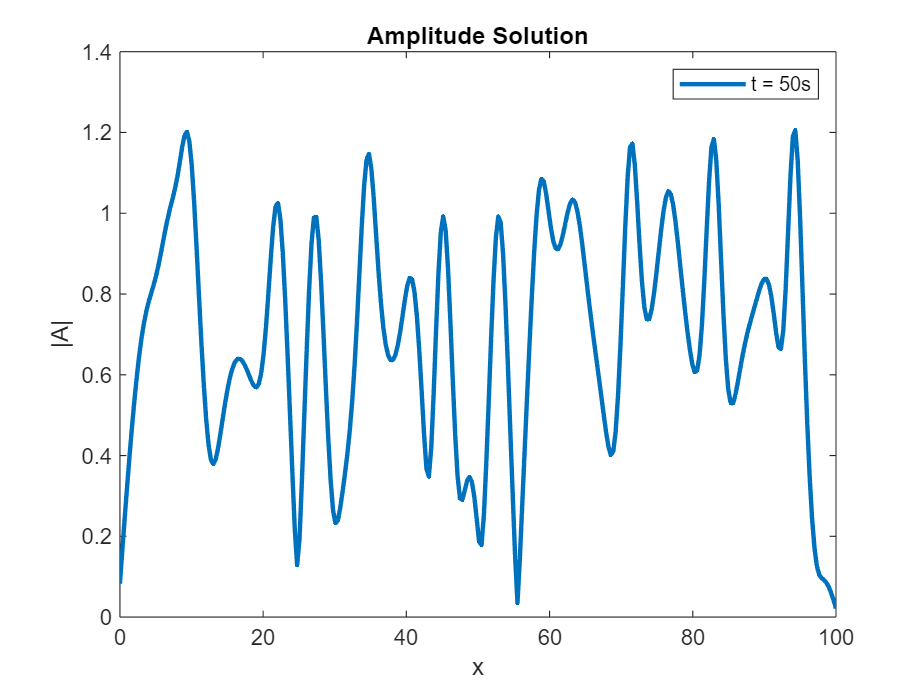

% Visualize the solution in the final time
figure;
plot(x, abs(A_time(:,end)), 'LineWidth', 2);
xlabel('x');
ylabel('|A|');
title('Amplitude Solution');
legend(['t = ' num2str(Tmax), 's']);

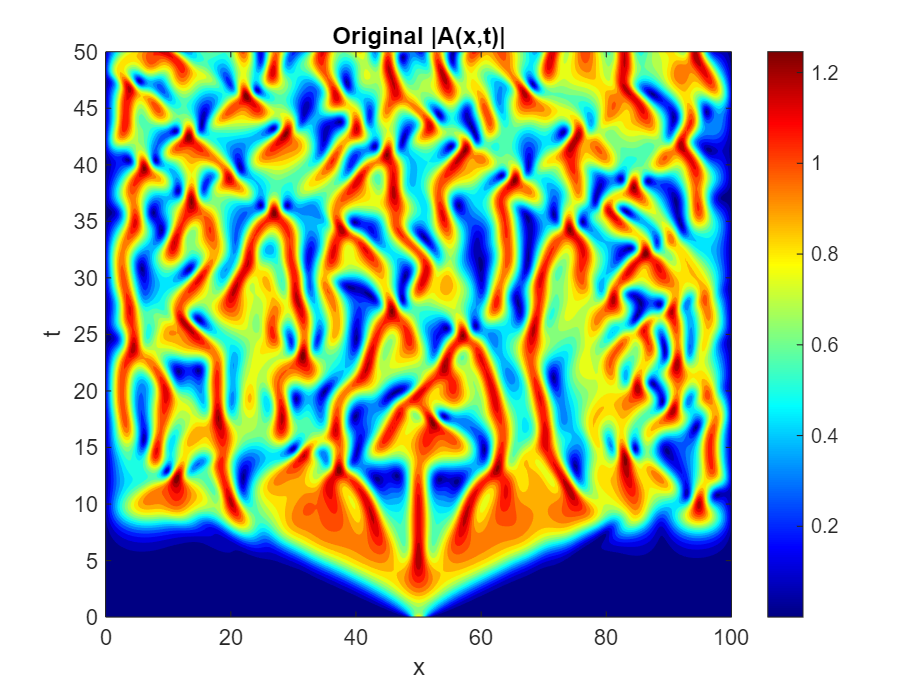

% Visualize the contour plot of the magnitude of A
figure;
contourf(x, t, abs(A_time)', 20, 'LineColor', 'none');
colorbar;
colormap jet;
xlabel('x');
ylabel('t');
title('Original |A(x,t)|');

% Save the simulation data
save('final_solution.mat', 'A_time', 'x', 't','dx','dt');